# **矩形谐振腔中的场分布**

**        谐振腔是中空的金属腔，电磁波可以在腔内以某种特定频率振荡，形成激励源。本节以矩形谐振腔为例来求谐振腔内电微场的解。**

**        这里假设a=22.86mm，b=10.16mm，c=22.86mm，用 MATLAB编程实现 TE 模在谐振腔中的动态显示。对于矩形谐振腔的主模TE101模，电磁场分量瞬时值形式为如下**


$$\begin{array}{l}
E_x (x,y,z,t)=0\\
E_y (x,y,z,t)=\frac{\omega a\mu }{\pi }H_m \sin (\frac{\pi }{a}x)\sin (\frac{\pi }{c}z)\sin (\omega t)\\
E_z (x,y,z,t)=0\\
H_x (x,y,z,t)=-\frac{a}{c}H_m \sin (\frac{\pi }{a}x)\cos (\frac{\pi }{c}z)\cos (\omega t)\\
H_y (x,y,z,t)=0\\
H_z (x,y,z,t)=H_m \cos (\frac{\pi }{a}x)\sin (\frac{\pi }{c}z)\cos (\omega t)
\end{array}$$


**        可绘制TE101模在谐振腔中的动态图**

**        是否绘制电场：**

clc
clear
E1=false;

**        是否绘制磁场：**

H1=true;

**        开始绘制：**

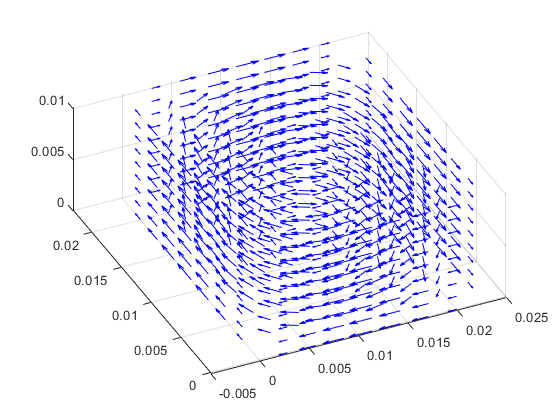

a=22.86;b=10.16;c=22.86;             	%谐振腔尺寸，单位为mm
a=a/1000; b=b/1000; c=c/1000;         	%转化单位为m
d=8;                              	%决定矢量的密集程度
H0=1;                             	%磁场z分量振幅
f=2.9153*10^10;
T=1/f;               	           %频率和周期
t=0;
lc=2*a;                             	%TE10截止波长
l0=3*10^8/f;                         	%工作波长
u=4*pi*10^(-7);                      	%磁导率
if(l0>lc)
        return;
else
        clf;
lg=l0/((1-(l0/lc)^2)^0.5);           	%波导波长
Beta=2*pi/lg;                    	%相移常数
w=Beta*3*10^8;                  	%角频率
x=0:a/d:a;
y=0:b/d:b;
z=0:c/d:c;
[x1,y1,z1]=meshgrid(x,y,z);
for i=1:150
    if H1
        hx=-a/c*H0.*sin(pi./a.*x1).*cos(pi./c.*z1)*cos(w*t);
        hz=H0.*cos(pi./a.*x1).*sin(pi./c.*z1).*cos(w*t);
        hy=zeros(size(y1));             	%磁场的三个分量
        H=quiver3(z1,x1,y1,hz,hx,hy,'b');
        hold on;
    end
    if E1
        ex=zeros(size(x1));
        ey=w.*u.*a.*H0.*sin(pi./a.*x1).*sin(pi./c.*z1).*sin(w*t)./pi;
        ez=zeros(size(z1));             	%电场的三个分量
        E=quiver3(z1,x1,y1,ez,ex,ey,'r');
    end
    view(-25,60);
    mov(i)=getframe(gcf);
    hold on
    t=t+T*0.1;
    hold off
end
end

- **动态展示**

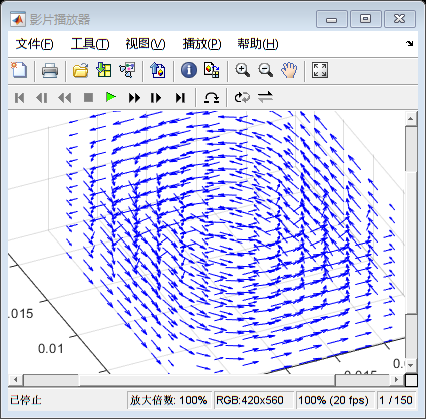

implay(mov);

- **保存为视频文件**

v=VideoWriter('矩形谐振腔.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)